# Homework 5  - Farshad Bolouri - R11630884

### Problem 1)

We wish to create a solution to decimate audio files from 48000 samples/second to 8000 samples/second, without

causing too much distortion to the frequencies that are kept.

clear
close all
[toneramp, tonerampFs] = audioread("new_toneramp.wav");
[equinox, equinoxFs] = audioread("equinox-48KHz.wav");

a) Design an anti-aliasing FIR filter that you consider appropriate for this purpose.

#### *Filter Design*

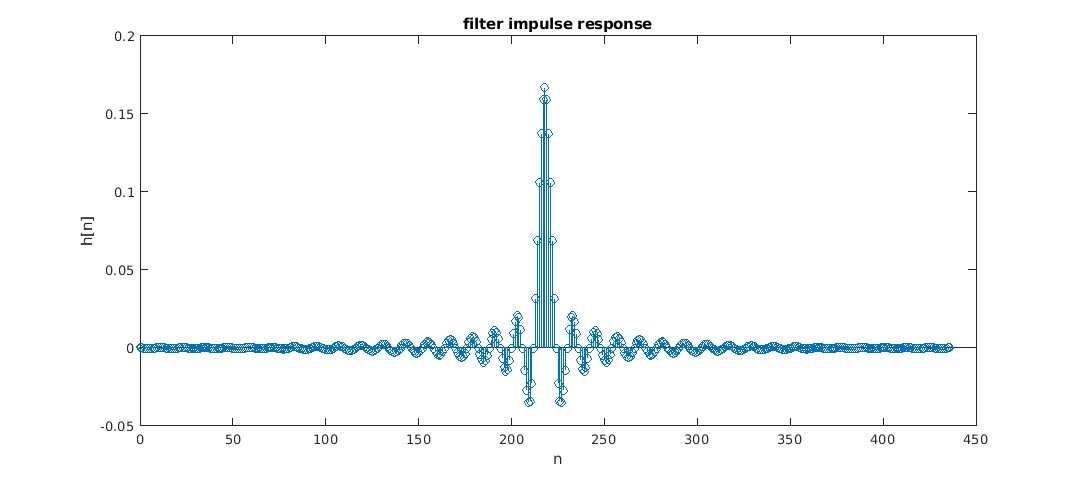

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

Fpass = 3800;            % Passband Frequency
Fstop = 4200;            % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.001;           % Stopband Attenuation
flag  = 'scale';         % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fpass Fstop]/(Fs/2), [1 0], [Dstop Dpass]);

% Calculate the coefficients using the FIR1 function.
h  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);

% graph filter impulse response
graph = figure;
stem(0:length(h)-1,h)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

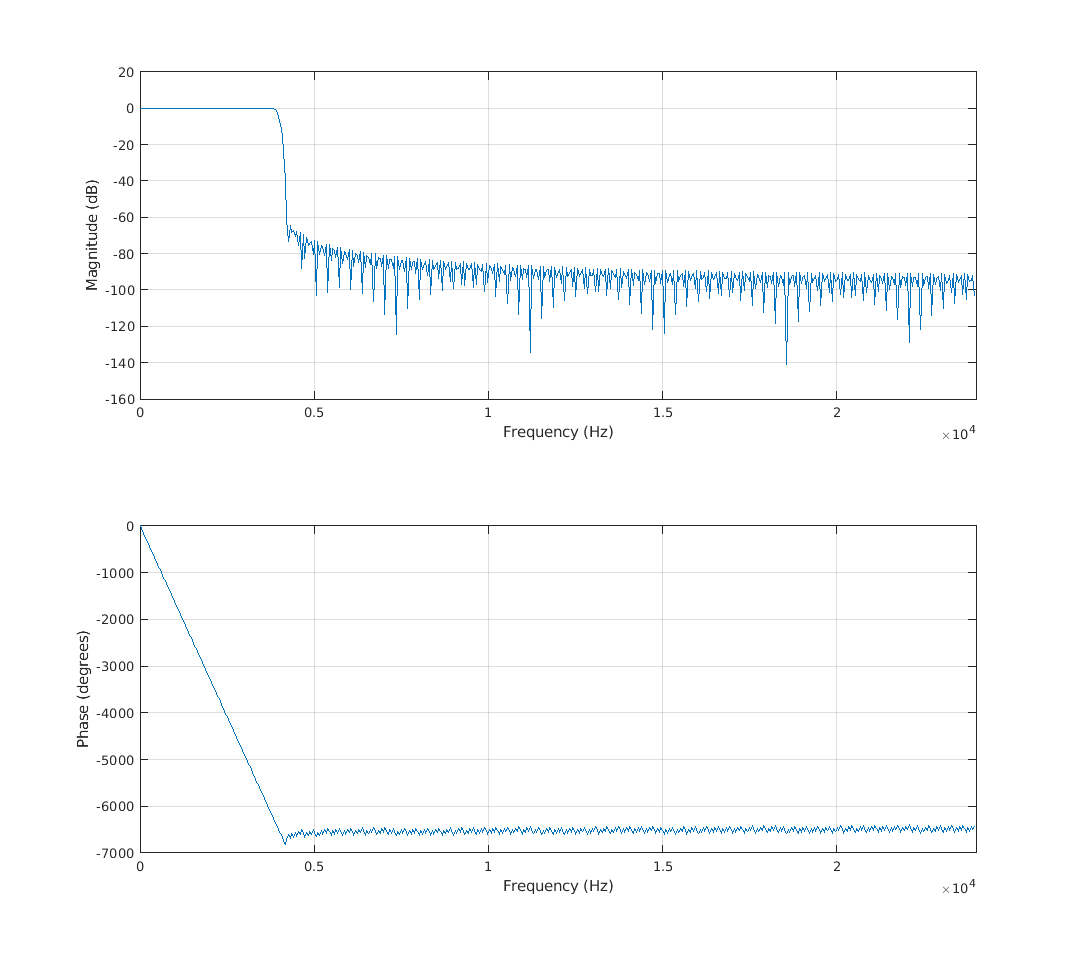

% graph filter frequency response
graph = figure;
freqz(h,1,[],equinoxFs)
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

*I chose my passband ripple to be 1 dB because I didn't want too much fluctuations in the frequencies that I am trying to keep.*

*I put the stopband attenuation to 60 dB  as I found to be enough to remove the frequecies that I don't want.*

*My *$f_s$* is at 48000 Hz as this is the sampling frequency of my original signal.*

*I put my *$f_c$* to 4000 Hz and the way I calculated this *$f_c$* was : *$\frac{\frac{f_s }{2}}{M}=\frac{\frac{48000}{2}\;\mathrm{Hz}}{6}=4000\;\mathrm{Hz}$*.*

*As we cannot apply an Ideal filter I put a transtion band for my filter, which is from 3800 Hz to 4200 Hz.*

*As for the choice of my design method, I tried designing the same filter with ****Equiripple, Kaiser Window****, and**** Least Squares.***

***Least Squares: ****For this filter, as it doesn't provide the "Minimum Order" option, I had to play with many orders and I was able*

#### *Applying the Filter*